# Part 1

clc;
clear;
syms theta d alpha a
syms L1 L2 L3 L4 L5 
syms theta_1 theta_2 theta_3 theta_4



lamda_1 = L1;
lamda_2 = sqrt(L3^2 + L2^2);
lamda_3 = L4 + L5;
beta = atan(L3/L2);

T = [ cos(theta) -sin(theta)*cos(alpha)  sin(theta)*sin(alpha) a*cos(theta);
      sin(theta)  cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);
          0             sin(alpha)            cos(alpha)            d;
          0                 0                     0                 1];

T01 = subs(T, [theta, d, a, alpha], [theta_1 lamda_1 0 -pi/2]);
T12 = subs(T, [theta, d, a, alpha], [-pi/2+beta+theta_2 0 lamda_2 0]);
T23 = subs(T, [theta, d, a, alpha], [-beta+theta_3 0 0 -pi/2]);
T34 = subs(T, [theta, d, a, alpha], [theta_4 lamda_3 0 0]);

T04 = T01 * T12 * T23 * T34;
T04 = simplify(T04);


# Part 2


function T04 = QArmForwardKinematics(theta_1, theta_2, theta_3,theta_4)
    L1 = 0.14;
    L2 = 0.35;
    L3 = 0.05;
    L4 = 0.25;
    L5 = 0.15;

    T04 = [sin(theta_1)*sin(theta_4) + cos(theta_1)*cos(theta_2)*cos(theta_4)*sin(theta_3) + cos(theta_1)*cos(theta_3)*cos(theta_4)*sin(theta_2), cos(theta_4)*sin(theta_1) - cos(theta_1)*cos(theta_2)*sin(theta_3)*sin(theta_4) - cos(theta_1)*cos(theta_3)*sin(theta_2)*sin(theta_4), cos(theta_2 + theta_3)*cos(theta_1), cos(theta_1)*sin(theta_2 + atan(L3/L2))*sqrt(L2^2 + L3^2) + cos(theta_2 + theta_3)*cos(theta_1)*(L4 + L5); cos(theta_2)*cos(theta_4)*sin(theta_1)*sin(theta_3) - cos(theta_1)*sin(theta_4) + cos(theta_3)*cos(theta_4)*sin(theta_1)*sin(theta_2), - cos(theta_1)*cos(theta_4) - cos(theta_2)*sin(theta_1)*sin(theta_3)*sin(theta_4) - cos(theta_3)*sin(theta_1)*sin(theta_2)*sin(theta_4), cos(theta_2 + theta_3)*sin(theta_1), sin(theta_1)*sin(theta_2 + atan(L3/L2))*sqrt(L2^2 + L3^2) + cos(theta_2 + theta_3)*sin(theta_1)*(L4 + L5); cos(theta_2 + theta_3)*cos(theta_4), -cos(theta_2 + theta_3)*sin(theta_4), -sin(theta_2 + theta_3), -(L2^2*L4*sin(theta_2 + theta_3) - L1*L3^2 - L1*L2^2 + L2^2*L5*sin(theta_2 + theta_3) + L3^2*L4*sin(theta_2 + theta_3) + L3^2*L5*sin(theta_2 + theta_3) - L2^2*cos(theta_2)*sqrt(L2^2 + L3^2)*sqrt((L2^2 + L3^2)/L2^2) + L2*L3*sin(theta_2)*sqrt(L2^2 + L3^2)*sqrt((L2^2 + L3^2)/L2^2))/(L2^2 + L3^2); sym(0), sym(0), sym(0), sym(1)];
end

T04 = QArmForwardKinematics(0, 0, 0,0);
T04 = round(T04,2)

$$T04 = \left(\begin{array}{cccc} 0 & 0 & 1.0 & 0.45\\ 0 & -1.0 & 0 & 0\\ 1.0 & 0 & 0 & 0.49\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

# Part 3

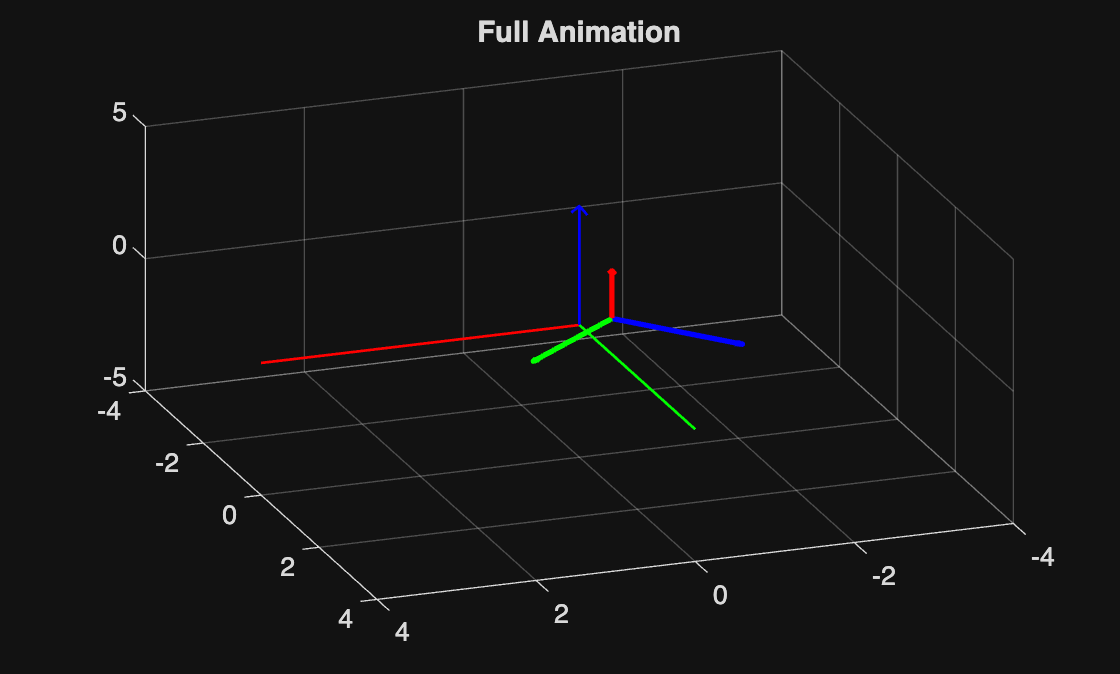

Unrecognized function or variable 'F_loop'.


x = 1;
graph_step = 40;
steps = 2;
Step_Size = graph_step * steps;
for i = 1:1:Step_Size
    cla
    if i == 1
        fig = figure(1);
        grid on
        grid minor
        view([160 40]);
        xlim([-4,4])
        ylim([-4,4])
        zlim([-5,5])
        title('Full Animation');
    end
    hold on

    if i <= graph_step
        index = i * 1/graph_step;
        T04 = QArmForwardKinematics(90*index, 0, 0,0);
    elseif i <= graph_step *2 
        index = (i-graph_step) * 1/graph_step;
        T04 = QArmForwardKinematics(90, 0, -90*index,0);
    else

    end


    % X-Axis
    quiver3(0,0,0,5,0,0, LineWidth=1,Color= "red")
    % Y-Axis
    quiver3(0,0,0,0,5,0, LineWidth=1,Color= "green" )
    % Z-Axis
    quiver3(0,0,0,0,0,5, LineWidth=1,Color= "blue" )
    
    % X-Axis
    quiver3(T04(1,4),T04(2,4),T04(3,4),T04(1,1)*2,T04(2,1)*2,T04(3,1)*2, LineWidth=2,Color= "red" )
    % Y-Axis
    quiver3(T04(1,4),T04(2,4),T04(3,4),T04(1,2)*2,T04(2,2)*2,T04(3,2)*2, LineWidth=2,Color= "green" )
    % Z-Axis
    quiver3(T04(1,4),T04(2,4),T04(3,4),T04(1,3)*2,T04(2,3)*2,T04(3,3)*2, LineWidth=2,Color= "blue" )
    hold off


    drawnow ('limitrate'); 
    frame = getframe(fig);
    im{x} = frame2im(frame);
    x = x + 1;
end